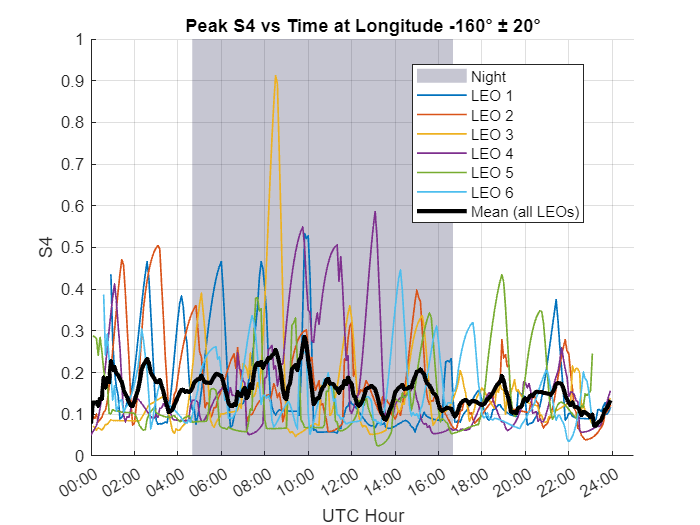

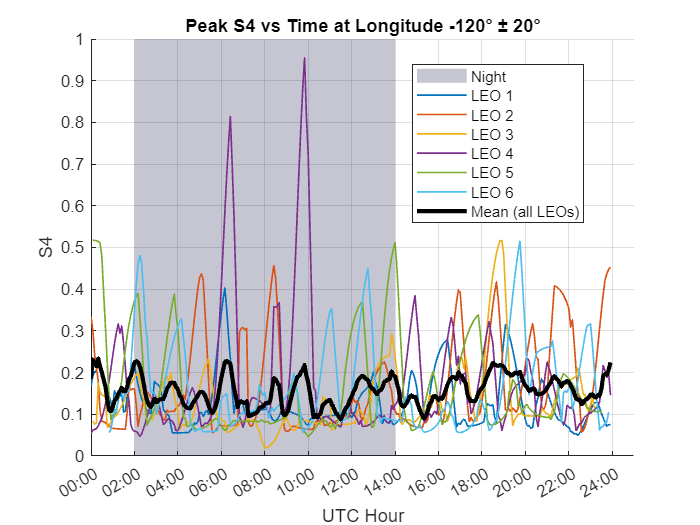

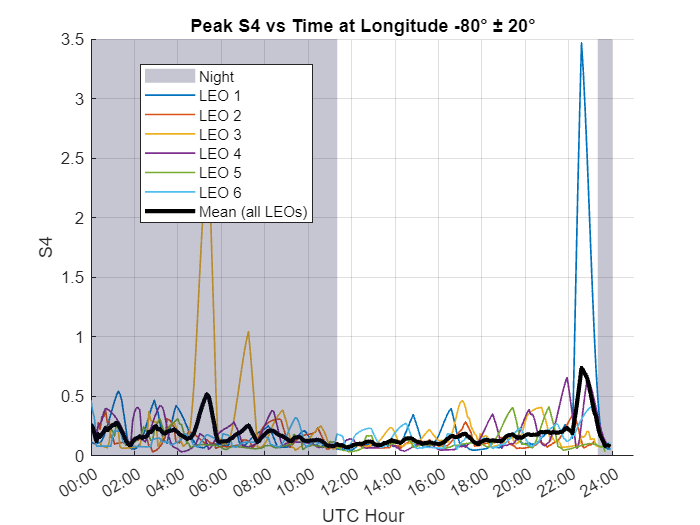

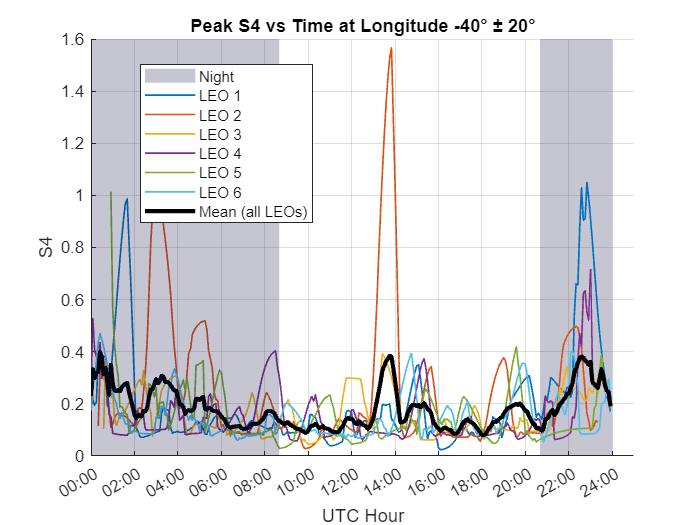

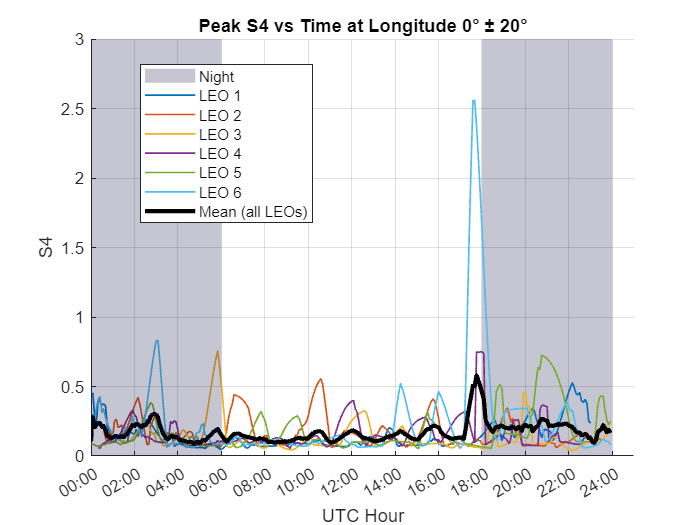

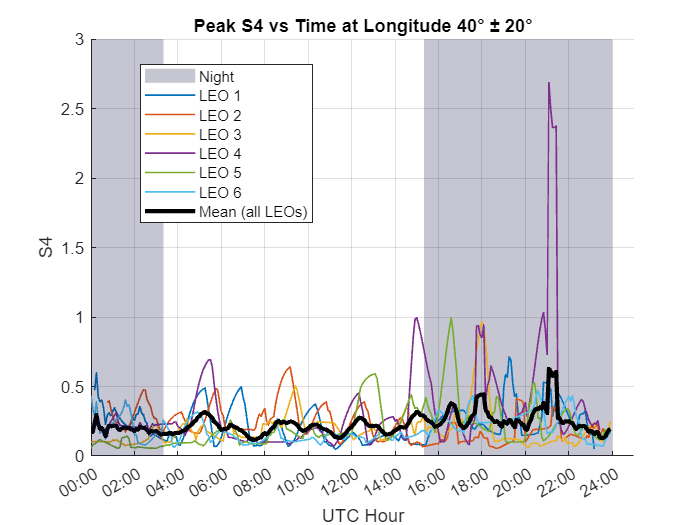

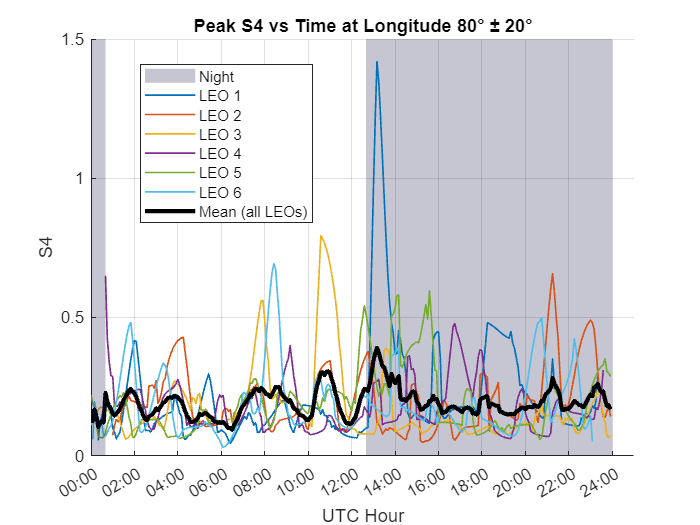

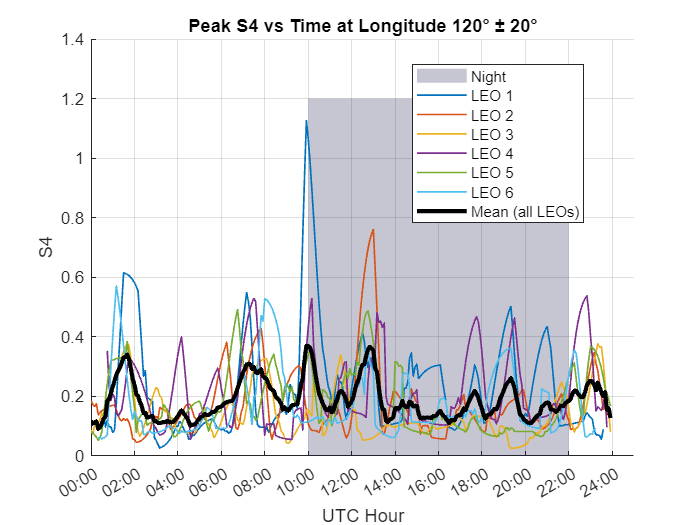

% S4 vs Time for fixed longitude
for target_lon = -160:40:160

    lon_tolerance = 20;
    time_grid     = 0:5:1435;
    all_S4_time_interp = NaN(6, length(time_grid));
    colors = lines(6);

    figure()
    hold on

    for leo = 1:6
        peak_S4   = [];
        peak_time = [];

        for i = 1:length(COSMIC_data)
            if COSMIC_data{i}.LEO_ID ~= leo
                continue
            end

            LON = COSMIC_data{i}.GEO_lon_LEO;
            S4  = COSMIC_data{i}.S4;
            valid = ~isnan(S4) & ~isnan(LON);
            S4  = S4(valid);
            LON = LON(valid);

            if isempty(S4), continue; end

            lon_mask = abs(LON - target_lon) <= lon_tolerance;
            S4 = S4(lon_mask);

            if isempty(S4), continue; end

            file_time = COSMIC_data{i}.hour*60 + COSMIC_data{i}.minute;

            [maxS4, ~] = max(S4);
            peak_S4(end+1,1)   = maxS4;
            peak_time(end+1,1) = file_time;
        end

        if isempty(peak_time) || length(peak_time) < 2
            fprintf('LEO %d: insufficient data points, skipping.\n', leo);
            continue
        end

        [peak_time_sorted, sort_idx] = sort(peak_time);
        peak_S4_sorted = peak_S4(sort_idx);

        [peak_time_sorted, unique_idx] = unique(peak_time_sorted);
        peak_S4_sorted = peak_S4_sorted(unique_idx);

        if length(peak_time_sorted) < 2
            fprintf('LEO %d: insufficient unique times after dedup, skipping.\n', leo);
            continue
        end

        in_range = time_grid >= peak_time_sorted(1) & time_grid <= peak_time_sorted(end);
        S4_interp = NaN(1, length(time_grid));
        S4_interp(in_range) = interp1(peak_time_sorted, peak_S4_sorted, ...
                                       time_grid(in_range), 'pchip', NaN);
        S4_interp = smoothdata(S4_interp, 'movmean', 5);

        all_S4_time_interp(leo, :) = S4_interp;

        plot(time_grid/60, S4_interp, ...
            'LineWidth', 1, ...
            'Color', colors(leo,:), ...
            'DisplayName', sprintf('LEO %d', leo));
    end


    mean_S4_time = mean(all_S4_time_interp, 1, 'omitnan');
    n_valid = sum(~isnan(all_S4_time_interp), 1);
    mean_S4_time(n_valid < 2) = NaN;

    plot(time_grid/60, mean_S4_time, ...
        'k-', 'LineWidth', 2.5, 'DisplayName', 'Mean (all LEOs)');

    % Night shading
    ax    = gca;
    y_lim = ylim(ax);


    utc_dusk = mod(18 - target_lon/15, 24); 
    utc_dawn = mod(6  - target_lon/15, 24);  

    % Convert to minutes for plotting
    night_start = utc_dusk * 60; 
    night_end   = utc_dawn * 60;  

    if night_start < night_end

        fill([night_start night_end night_end night_start]/60, ...
             [y_lim(1) y_lim(1) y_lim(2) y_lim(2)], ...
             [0.1 0.1 0.3], 'FaceAlpha', 0.25, 'EdgeColor', 'none', ...
             'DisplayName', 'Night', 'HandleVisibility', 'on');
    else

        fill([night_start 24*60 24*60 night_start]/60, ...
             [y_lim(1) y_lim(1) y_lim(2) y_lim(2)], ...
             [0.1 0.1 0.3], 'FaceAlpha', 0.25, 'EdgeColor', 'none', ...
             'DisplayName', 'Night', 'HandleVisibility', 'on');

        fill([0 night_end night_end 0]/60, ...
             [y_lim(1) y_lim(1) y_lim(2) y_lim(2)], ...
             [0.1 0.1 0.3], 'FaceAlpha', 0.25, 'EdgeColor', 'none', ...
             'HandleVisibility', 'off');
    end

    % Push night shading behind data lines
    night_patches = findobj(gca, 'Type', 'patch');
    uistack(night_patches, 'bottom');

    xlabel('UTC Hour')
    ylabel('S4')
    title(sprintf('Peak S4 vs Time at Longitude %d° ± %d°', target_lon, lon_tolerance))

    xticks(0:2:24)
    xticklabels(arrayfun(@(h) sprintf('%02d:00', h), 0:2:24, 'UniformOutput', false))

    legend('Location', 'best')
    grid on
    hold off
end